clear; close all; clc

## TO DO

% Handle NAN values
% Keep working on dataset

% Read Data
housing_data = readtable('housing.csv');

% Plot some stuff out here
table(housing_data);

Unrecognized function or variable 'housing_data'.

## Categorical data treatment

% Could be looped
% Initial idea to convert to separate boolean columns
hour_ocean = cell(size(housing_data, 1),1);
hour_ocean(strcmp(housing_data.ocean_proximity, '<1H OCEAN')) = {1};
hour_ocean(~strcmp(housing_data.ocean_proximity, '<1H OCEAN')) = {0};

% Other var
is_inland = cell(size(housing_data, 1),1);
is_inland(strcmp(housing_data.ocean_proximity, 'INLAND')) = {1};
is_inland(~strcmp(housing_data.ocean_proximity, 'INLAND')) = {0};

% Is island
is_island = cell(size(housing_data, 1),1);
is_island(strcmp(housing_data.ocean_proximity, 'ISLAND')) = {1};
is_island(~strcmp(housing_data.ocean_proximity, 'ISLAND')) = {0};


% Is near bay
is_near_bay = cell(size(housing_data, 1),1);
is_near_bay(strcmp(housing_data.ocean_proximity, 'NEAR BAY')) = {1};
is_near_bay(~strcmp(housing_data.ocean_proximity, 'NEAR BAY')) = {0};

% Is near ocean
is_near_ocean = cell(size(housing_data, 1),1);
is_near_ocean(strcmp(housing_data.ocean_proximity, 'NEAR OCEAN')) = {1};
is_near_ocean(~strcmp(housing_data.ocean_proximity, 'NEAR OCEAN')) = {0};

## Handle NAN values

% Set to median value of column

nan_columns = false(1,width(housing_data));

for col = 1:width(housing_data)
    if isnumeric(housing_data{:, col})  % Check if the column is numeric
        nan_columns(col) = any(isnan(housing_data{:, col}));
    end
end

nan_containing_columns = find(nan_columns);

if ~isempty(nan_containing_columns)
    fprintf('Columns containing NaN values: %s\n', num2str(nan_containing_columns));
else
    fprintf('No columns contain NaN values.\n');
end

Columns containing NaN values: 5



% Column 5 contains NaN values

nan_count = sum(isnan(housing_data{:,5}));
non_nan_count = sum(~isnan(housing_data{:,5}));
percentage = nan_count / size(housing_data, 1);
fprintf(['Nan amount in column 5', int2str(nan_count)]);

Nan amount in column 5207

disp(percentage);

    0.0100




column_5_median = median(housing_data{:,5},'omitnan');
column_5_mean = mean(housing_data{:,5},'omitnan');

disp(column_5_median);

   435




housing_data(isnan(housing_data{:, 5}), 5) = {column_5_mean};

% Show nan count now
new_nan_count = sum(isnan(housing_data{:,5}));
disp(new_nan_count);

     0



% Add new columns to data

housing_data = [housing_data is_inland is_island is_near_ocean is_near_bay hour_ocean]

housing_data = 20640×15 table
    longitude    latitude    housing_median_age    total_rooms    total_bedrooms    population    households    median_income    median_house_value    ocean_proximity    Var11    Var12    Var13    Var14    Var15
    _________    ________    __________________    ___________    ______________    __________    __________    _____________    __________________    _______________    _____    _____    _____    _____    _____

     -122.23      37.88            


% Rename some columns for myself
housing_data.Properties.VariableNames{11} = 'is_inland'

housing_data = 20640×15 table
    longitude    latitude    housing_median_age    total_rooms    total_bedrooms    population    households    median_income    median_house_value    ocean_proximity    is_inland    Var12    Var13    Var14    Var15
    _________    ________    __________________    ___________    ______________    __________    __________    _____________    __________________    _______________    _________    _____    _____    _____    _____

     -122.23      37.88    

housing_data.Properties.VariableNames{12} = 'is_island'

housing_data = 20640×15 table
    longitude    latitude    housing_median_age    total_rooms    total_bedrooms    population    households    median_income    median_house_value    ocean_proximity    is_inland    is_island    Var13    Var14    Var15
    _________    ________    __________________    ___________    ______________    __________    __________    _____________    __________________    _______________    _________    _________    _____    _____    _____

     -122.23      3

housing_data.Properties.VariableNames{13} = 'is_near_ocean'

housing_data = 20640×15 table
    longitude    latitude    housing_median_age    total_rooms    total_bedrooms    population    households    median_income    median_house_value    ocean_proximity    is_inland    is_island    is_near_ocean    Var14    Var15
    _________    ________    __________________    ___________    ______________    __________    __________    _____________    __________________    _______________    _________    _________    _____________    _____    _____

   

housing_data.Properties.VariableNames{14} = 'is_near_bay'

housing_data = 20640×15 table
    longitude    latitude    housing_median_age    total_rooms    total_bedrooms    population    households    median_income    median_house_value    ocean_proximity    is_inland    is_island    is_near_ocean    is_near_bay    Var15
    _________    ________    __________________    ___________    ______________    __________    __________    _____________    __________________    _______________    _________    _________    _____________    ___________    _____</

housing_data.Properties.VariableNames{15} = 'hour_ocean'

housing_data = 20640×15 table
    longitude    latitude    housing_median_age    total_rooms    total_bedrooms    population    households    median_income    median_house_value    ocean_proximity    is_inland    is_island    is_near_ocean    is_near_bay    hour_ocean
    _________    ________    __________________    ___________    ______________    __________    __________    _____________    __________________    _______________    _________    _________    _____________    ___________    __

% Store header values
treated_values_header = housing_data.Properties.VariableNames;

% Features
X = housing_data(:,[1:8,10:end]);
X = removevars(X,"ocean_proximity");
X = table2array(X);
% Labels
Y = housing_data(:,"households");
Y = table2array(Y);

% Dataset size
rows = size(housing_data, 1);
disp(rows);

       20640




% Randomize indicies
random_indicies = randperm(rows);

% Define calibration amount
calibration_split_point = 0.7;

% Row to split at
row_to_split_data_at = round(calibration_split_point * rows);

% Split into test and calibration units
X_calibration = X(random_indicies(1:row_to_split_data_at),:);
Y_calibration = Y(random_indicies(1:row_to_split_data_at),:);

X_test = X(random_indicies(row_to_split_data_at + 1:end),:);
Y_test = Y(random_indicies(row_to_split_data_at + 1:end),:);


% Mean and std of calibration data

X_calibration_mean = mean(X_calibration);
Y_calibration_mean = mean(Y_calibration);

X_calibration_std = std(X_calibration);
Y_calibration_std = std(Y_calibration);


% Zscore the calibration data
z_X_calibration = zscore(X_calibration);
%z_Y_calibration(Y_calibration);
z_Y_calibration = zscore(Y_calibration);

% Visualize component amount to make a decision
[coeff, score, latent, tsquared, explained, mu] = pca(z_X_calibration);

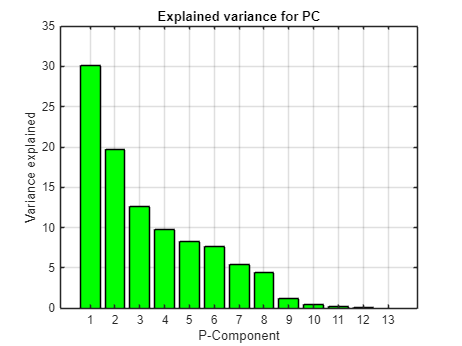


% Explained variance by PC
figure;
bar(explained, 'g');
xlabel('P-Component');
ylabel('Variance explained');
title('Explained variance for PC');
grid on;

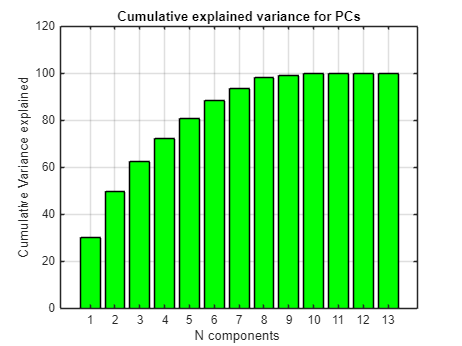

% Cumulative explained variance
% Cumulative variance - Plotted to see total explanation of combination of
% PC's
cumulative_variance = cumsum(explained);
bar(cumulative_variance, 'g');
xlabel('N components ');
ylabel('Cumulative Variance explained');
title('Cumulative explained variance for PCs');
grid on;

% Based off the graphs around 6 components explain 84-85% of variance so
% select 6 components
component_amount = 6;

% PLS model
% [XL,YL,XS,YS,BETA,PCTVAR,MSE,stats]
[XL,YL,XS,YS,BETA,PCTVAR,MSE,stats]= plsregress(z_X_calibration, z_Y_calibration, component_amount);
disp(XL);

   14.3308  -85.3706   64.0347    0.5940  -22.6682   29.8764
  -14.6713   75.6693  -77.7431   25.0213    4.7663  -30.5943
  -46.7316   64.5298   65.3156   -6.1735    6.1932  -33.7208
  114.9662    1.4463  -14.3762   -4.3789    2.2753  -14.5912
  117.0069   13.1869    6.0865   12.4441    6.9651    3.8736
  112.5455    5.3001    3.5223  -13.2011  -23.3857   -7.9807
  117.6728   14.3529    7.8879    9.7122   10.8582    6.3511
    8.6284  -42.7932  -41.8077  -46.9885   72.6370  -29.9483
   -3.3750   -7.6803  -59.9226   83.7154  -48.2136    0.3010
   -1.4646    1.5629    3.6850   -3.9034   -2.6454   16.1159
   -1.2848    2.5958   18.1400   -7.6585   -1.6059   23.9308
   -7.9912   80.3991  -29.1369  -57.9370   18.5494   44.1196
    9.1286  -45.4654   61.8288  -36.1761   34.4772  -45.0675



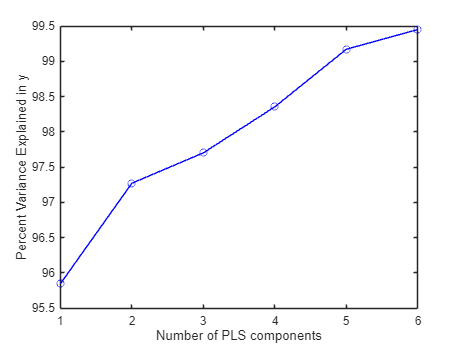

% PLS explained variance
plot(1:component_amount,cumsum(100*PCTVAR(2,:)),'-bo');
xlabel('Number of PLS components');
ylabel('Percent Variance Explained in y');

% PCR Regression

% Get first 6 components
X_PCR = score(:,1:component_amount)

X_PCR =    -0.3224   -2.2618    0.0165   -0.5446   -0.0410   -0.0305
    1.4071   -0.7423   -0.2859    2.9717    0.2497   -0.0318
   -1.0071    1.2889    1.5650   -0.5231    0.9404    0.1932
    2.7271    3.0112   -1.9708    0.0720    0.2734    0.1277
   -0.5288   -0.2534   -0.0528    2.6563    1.0669    0.1091
   -1.1159   -0.0340   -1.3193   -0.7355   -0.6604   -0.1741
   -0.2794   -1.4994   -0.4202   -0.5930   -0.2771   -0.0817
   -0.4094   -0.8876   -0.5507   -0.8059    0.7333    0.1272
   -0.6946   -1.9062   -0.3834   -0.6118    0.3541    0.0560
   -1.2133   -1.8948   -0.7357   -0.4817   -0.4490   -0.1128


B_PCR = regress(z_Y_calibration, [ones(size(X_PCR, 1), 1), X_PCR]);

disp('PCR Regression Coefficients:');

PCR Regression Coefficients:


disp(B_PCR);

    0.0000
    0.4860
    0.0925
   -0.0674
    0.0299
   -0.1175
   -0.0231



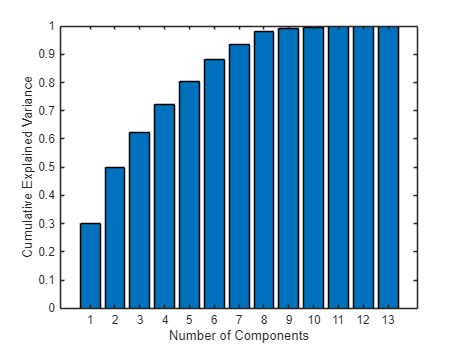

% PCR Explained variance This needs more work

explained_variance_X = latent ./ sum(latent); % Fraction of variance explained by each PC
cumulative_explained_X_PCR = cumsum(explained_variance_X);
figure;

bar(cumulative_explained_X_PCR);
xlabel('Number of Components');
ylabel('Cumulative Explained Variance');